## 1

## a


frases = {"just plain boring", "entirely predictable and lacks energy", "no surprises and very few laughs", "very powerful", "the most fun film of the summer"};
P1 = [];
for i = 1:length(frases)
    palavras = split(frases{i});
    P1 = [P1; palavras];
end
P = unique(P1)

P = 20×1 string array
    "and"
    "boring"
    "energy"
    "entirely"
    "few"
    "film"
    "fun"
    "just"
    "lacks"
    "laughs"
    "most"
    "no"
    "of"
    "plain"
    "powerful"
    "predictable"
    "summer"
    "surprises"
    "the"
    "very"


## b

OC = zeros(length(frases), length(P));
for i = 1:length(frases)
    palavras = split(frases{i});
        for j = 1:length(P)
            OC(i, j) = sum(strcmp(P{j}, palavras));
        end
end

## c

cat = ['-','-','-','+','+']'

cat = 5×1 char array
    '-'
    '-'
    '-'
    '+'
    '+'


## d

pNEG = sum(cat == '-')/length(cat);
pPOS = sum(cat == '+')/length(cat);

linhas_classe = cat == '+';
TREINO_CLASSE = OC(linhas_classe,:);
OCORRENCIAS = sum(TREINO_CLASSE)+1;
TOTAL = sum(TREINO_CLASSE(:)) + length(P);

probP = OCORRENCIAS/TOTAL

probP =     0.0345    0.0345    0.0345    0.0345    0.0345    0.0690    0.0690    0.0345    0.0345    0.0345    0.0690    0.0345    0.0690    0.0345    0.0690    0.0345    0.0690    0.0345    0.1034    0.0690




linhas_classe = cat == '-';
TREINO_CLASSE = OC(linhas_classe,:);
OCORRENCIAS = sum(TREINO_CLASSE)+1;
TOTAL = sum(TREINO_CLASSE(:)) + length(P);

probN = OCORRENCIAS/TOTAL

probN =     0.0882    0.0588    0.0588    0.0588    0.0588    0.0294    0.0294    0.0588    0.0588    0.0588    0.0294    0.0588    0.0294    0.0588    0.0294    0.0588    0.0294    0.0588    0.0294    0.0588




palavras_teste = {'predictable', 'no', 'fun'}

palavras_teste = 1×3 cell array
    {'predictable'}    {'no'}    {'fun'}


for p = 1:length(P)
   if P(p) == 'predictable'
     indexp = p;
   end

   if P(p) == 'no'
     indexn = p;
   end

   if P(p) == 'fun'
     indexf = p;
   end
end

probP_IF_POS = probP(indexp) 

probP_IF_POS = 0.0345

probN_IF_POS = probP(indexn)

probN_IF_POS = 0.0345

probF_IF_POS = probP(indexf)

probF_IF_POS = 0.0690


probPOS = probF_IF_POS * probP_IF_POS * probN_IF_POS

probPOS = 8.2004e-05

## 2 a)

M = readcell("PL5Ex2(in).csv")

M = 21×11 cell array
    {'Email'}    {'Other'}    {'Click'}    {'Free'}    {'Money'}    {'Meeting'}    {'Project'}    {'Win'}    {'Urgent'}    {'Prize'}    {'Class'}
    {[    1]}    {[    1]}    {[    1]}    {[   0]}    {[    1]}    {[      0]}    {[      0]}    {[  1]}    {[     1]}    {[    1]}    {'SPAM' }
    {[    2]}    {[    0]}    {[    0]}    {[   0]}    {[    0]}    {[      1]}    {[      1]}    {[  0]}    {[     0]}    {[    0]}    {'OK'   }
    {[    3]}    {[    1]}    {[    0]}    {[   1]}    {[    1]}    {[      0]}    {[      0]}    {[  1]}    {[     0]}    {[    0]}    {'SPAM' }
    {[    4]}    {[    0]}    {[    0]}    {[   0]}    {[    0]}    {[      1]}    {[      0]}    {[  0]}    {[     0]}    {[    0]}    {'OK'   }
    {[    5]}    {[    1]}    {[    1]}    {[   0]}    {[    1]}    {[      0]}    {[      0]}    {[  1]}    {[     1]}    {[    1]}    {'SPAM' }
    {[    6]}    {[    0]}    {[    0]}    {[   0]}    {[    0]}    {[      1]}    {[      1]}    {[  0

caracteristicas = M(1,2:end-1)

caracteristicas = 1×9 cell array
    {'Other'}    {'Click'}    {'Free'}    {'Money'}    {'Meeting'}    {'Project'}    {'Win'}    {'Urgent'}    {'Prize'}


X = M(2:end, 2:end-1);
X = cell2mat(X)

X =      1     1     0     1     0     0     1     1     1
     0     0     0     0     1     1     0     0     0
     1     0     1     1     0     0     1     0     0
     0     0     0     0     1     0     0     0     0
     1     1     0     1     0     0     1     1     1
     0     0     0     0     1     1     0     0     0
     1     0     1     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0
     1     1     1     1     0     0     1     1     1
     0     0     0     0     1     1     0     0     0


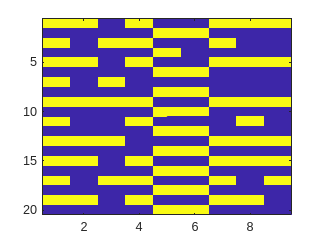

imagesc(X)

classes = M(2:end,end)

classes = 20×1 cell array
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }


nomes_classes = unique(classes)

nomes_classes = 2×1 cell array
    {'OK'  }
    {'SPAM'}



C1 = cell2mat(nomes_classes(1)) %ok

C1 = 'OK'

C2 = cell2mat(nomes_classes(2)) %spam

C2 = 'SPAM'

## b)

permutacao = randperm(size(X, 1))

permutacao =     10     6     4     2    16     7    14    15    13    17    18     1     8     5     3    12     9    20    19    11


num_linhas_treino = 0.7 * size(X, 1)

num_linhas_treino = 14

TREINO = X(permutacao(1:num_linhas_treino),:)

TREINO =      0     0     0     0     1     1     0     0     0
     0     0     0     0     1     1     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     1     1     0     0     0
     0     0     0     0     1     1     0     0     0
     1     0     1     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0
     1     1     0     1     0     0     1     1     1
     1     1     1     0     0     0     1     1     1
     1     0     1     1     0     0     1     0     1


TESTE = X(permutacao(num_linhas_treino+1:end),:)

TESTE =      1     0     1     1     0     0     1     0     0
     0     0     0     0     1     1     0     0     0
     1     1     1     1     0     0     1     1     1
     0     0     0     0     1     1     0     0     0
     1     1     0     1     0     0     1     1     0
     1     0     0     1     0     0     0     1     0


classes_treino = classes(permutacao(1:num_linhas_treino),:)

classes_treino = 14×1 cell array
    {'OK'  }
    {'OK'  }
    {'OK'  }
    {'OK'  }
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'SPAM'}
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}


classes_teste = classes(permutacao(num_linhas_treino+1:end),:)

classes_teste = 6×1 cell array
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'OK'  }
    {'SPAM'}
    {'SPAM'}


unique_classes = unique(classes)

unique_classes = 2×1 cell array
    {'OK'  }
    {'SPAM'}


## c)

pOK = sum(strcmp(classes_treino, C1))/length(classes_treino)

pOK = 0.5714

pSPAM = sum(strcmp(classes_treino, C2))/length(classes_treino)

pSPAM = 0.4286

## d)

pifC1 = prob_if_class(C1, classes_treino, TREINO);
pifC2 = prob_if_class(C2, classes_treino, TREINO);

## e)

% com ajuda

probs = cell(1, size(TESTE, 1));

for i = 1:size(TESTE, 1)
    p1 = prob_class(TESTE(i, :), pifC1, pOK);
    p2 = prob_class(TESTE(i, :), pifC2, pSPAM);
    [~, index] = max([p1 p2]);
    probs{i} = unique_classes{index};
end

probs = cellfun(@string, probs, 'UniformOutput', false);
classes_teste = cellfun(@string, classes_teste', 'UniformOutput', false);

correct_predictions = zeros(1, length(probs));

for i = 1:length(correct_predictions)
    correct_predictions(i) = strcmp(probs{i}, classes_teste{i});
end

P = sum(correct_predictions) / length(classes_teste) * 100;

fprintf('Precisão: %.2f%%\n', P);

Precisão: 100.00%



R1 = recall(C1, probs, classes_teste);
R2 = recall(C2, probs, classes_teste);

fprintf("Recall para 'OK': %.2f%%\n", R1);

Recall para 'OK': 100.00%


fprintf("Recall para 'SPAM': %.2f%%\n", R2);

Recall para 'SPAM': 100.00%



R = mean([R1 R2], "omitmissing");

F_1 = 2 * P * R / (P + R);
fprintf("F_1: %.2f%%\n", F_1);

F_1: 100.00%


## 3 

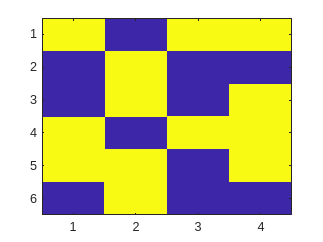

% [Ação?, Comédia?, Duração, Num de avaliações positivas]
X = [1 0 1 1;
     0 1 0 0; 
     0 1 0 1; 
     1 0 1 1;
     1 1 0 1; 
     0 1 0 0];

classes = categorical({'Interessa', 'Não Interessa', 'Interessa', 'Interessa', 'Interessa', 'Não Interessa'});

imagesc(X);


C1 = 'Interessa';
C2 = 'Não Interessa';

pINT = sum(classes == C1)/length(classes)

pINT = 0.6667

pNINT = sum(classes == C2)/length(classes)

pNINT = 0.3333


linhas_classe1 = classes == C1;
TREINO_CLASSE1 = X(linhas_classe1,:);
OCORRENCIAS = sum(TREINO_CLASSE1);
TOTAL = sum(sum(TREINO_CLASSE1)) 

TOTAL = 11


probifINT = OCORRENCIAS/TOTAL

probifINT =     0.2727    0.1818    0.1818    0.3636



linhas_classe2 = classes == C2;
TREINO_CLASSE2 = X(linhas_classe2,:);
OCORRENCIAS = sum(TREINO_CLASSE2);
TOTAL = sum(sum(TREINO_CLASSE2)); %size(TREINO_CLASSE,1)

probifNINT = OCORRENCIAS/TOTAL

probifNINT =      0     1     0     0




teste = [1 0 1 1];
fprintf("a)");

a)

% P(c1 | teste)
p1 = 1;
for i = 1:length(probifINT)
    if teste(i) ~= 0
        p1 = p1 * probifINT(i);
    end
end
p2 = 1;
for i = 1:length(probifNINT)
    if teste(i) ~= 0
        p2 = p2 * probifNINT(i);
    end
end

p1 = p1 * pINT

p1 = 0.0120

p2 = p2 * pNINT

p2 = 0


if (p1 > p2)
    a = C1;
else
    a = C2;
end

teste = [0 1 0 0];

fprintf("b)");

b)

p1 = 1;
for i = 1:length(probifINT)
    if teste(i) ~= 0
        p1 = p1 * probifINT(i);
    end
end
p2 = 1;
for i = 1:length(probifNINT)
    if teste(i) ~= 0
        p2 = p2 * probifNINT(i);
    end
end

p1 = p1 * pINT

p1 = 0.1212

p2 = p2 * pNINT

p2 = 0.3333


if (p1 > p2)
    b = C1;
else
    b = C2;
end


teste = [1 1 0 0];

fprintf("c)");

c)

p1 = 1;
for i = 1:length(probifINT)
    if teste(i) ~= 0
        p1 = p1 * probifINT(i);
    end
end
p2 = 1;
for i = 1:length(probifNINT)
    if teste(i) ~= 0
        p2 = p2 * probifNINT(i);
    end
end

p1 = p1 * pINT

p1 = 0.0331

p2 = p2 * pNINT

p2 = 0


if (p1 > p2)
    c =C1;
else
    c =C2;
end

fprintf(" a) %s\n b) %s\n c) %s\n",a,b,c);

 a) Interessa
 b) Não Interessa
 c) Interessa
